clc;clear;close all;
load nspeech2.mat;
%sound(nspeech2);

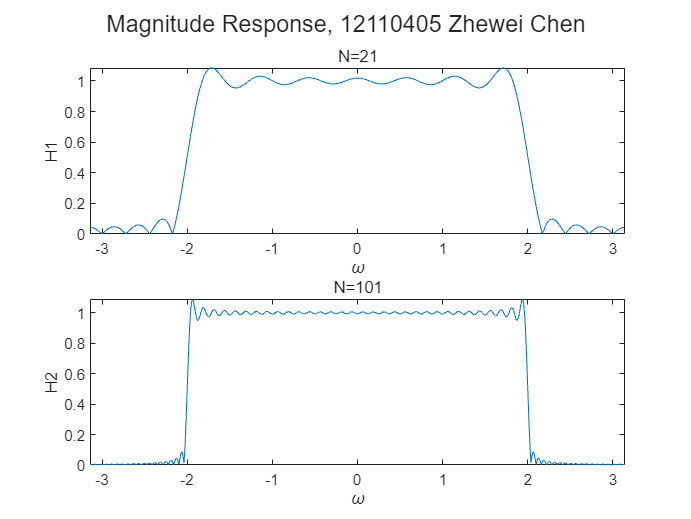


h1=LPFtrunc(21);
h2=LPFtrunc(101);

[X1,w1]=DTFT(h1,512);
[X2,w2]=DTFT(h2,512);

figure
sgtitle('Magnitude Response, 12110405 Zhewei Chen')
subplot(211);plot(w1,abs(X1));xlabel('\omega');ylabel('H1');xlim([-pi,pi]),title('N=21')
subplot(212);plot(w2,abs(X2));xlabel('\omega');ylabel('H2');xlim([-pi,pi]),title('N=101')

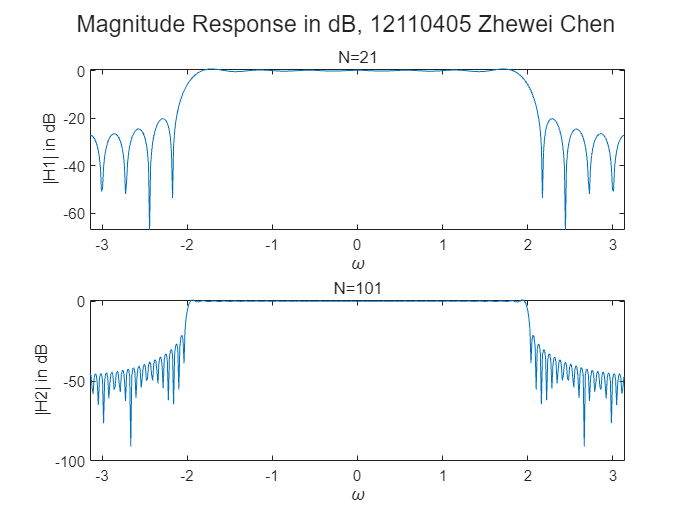


figure
sgtitle('Magnitude Response in dB, 12110405 Zhewei Chen')
subplot(211);plot(w1,20*log10(abs(X1)));xlabel('\omega');ylabel('|H1| in dB');xlim([-pi,pi]),title('N=21')
subplot(212);plot(w2,20*log10(abs(X2)));xlabel('\omega');ylabel('|H2| in dB');xlim([-pi,pi]),title('N=101')

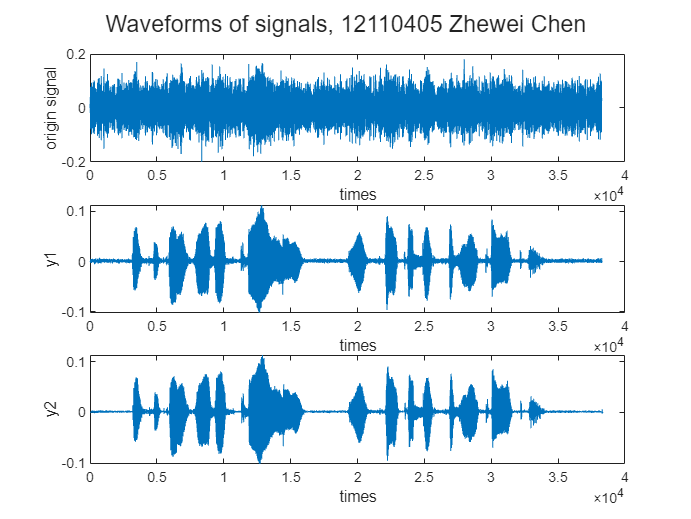

figure
sgtitle('Waveforms of signals, 12110405 Zhewei Chen')

y1=conv(h1,nspeech2);

sound(y1);
y2=conv(h2,nspeech2);
subplot(311);plot(nspeech2);xlabel('times');ylabel('origin signal');
subplot(312);plot(y1);xlabel('times');ylabel('y1');
subplot(313);plot(y2);xlabel('times');ylabel('y2');

% sound(y2);
